clc; clear;
% Ryan Mittelstadt 
% Airplane landing gear: Sensitivity Analysis

% Constants
m = 1200;             % mass (kg)
v0 = 0.56;            % initial vertical speed (m/s)
x0 = 0;               % initial displacement (m)
tspan = [0 5];        % simulation time (seconds)

% Parameter sweep
k_values = linspace(1e3, 1e4, 50);          % N/m
zeta_values = linspace(0.1, 1.0, 50);      % unitless

% Initialize result matrices
settling_times = zeros(length(k_values), length(zeta_values));
max_forces = zeros(length(k_values), length(zeta_values));

% Loop through all k and zeta combinations
for i = 1:length(k_values)
    for j = 1:length(zeta_values)
        k = k_values(i);
        zeta = zeta_values(j);
        c = 2*zeta*sqrt(k*m);   % damping coefficient

        % Define ODE system
        ode = @(t, y)[ y(2); -(c/m)*y(2)-(k/m)*y(1) ];
        y0 = [x0; v0]; % Initial Conditions

        % Solve ODE
        [t, y] = ode45(ode, tspan, y0);
        x = y(:,1);  % Position
        v = y(:,2);  % Velocity

        % Define settling tolerance band (±5% of peak displacement)
        peak = max(abs(x));
        tol = 0.05 * peak;

        % Find last time x(t) goes outside ±tol
        out_of_bounds = find(abs(x) > tol);
        if isempty(out_of_bounds)
            settling_time = 0; % Catch-all
        else
            settling_time = t(out_of_bounds(end));
        end

        % Calculate the force at each time point
        F = c*v + k*x;  % Force formula
        
        % Find the maximum force exerted during the simulation
        max_force = max(abs(F));

        % Store results
        settling_times(i, j) = settling_time;
        max_forces(i, j) = max_force;
    end
end

% Find best result
[min_settling_time, min_idx] = min(settling_times(:));
[min_k_idx, min_zeta_idx] = ind2sub(size(settling_times), min_idx);
min_k = k_values(min_k_idx);
min_zeta = zeta_values(min_zeta_idx);
force_at_min_settling_time = max_forces(min_k_idx, min_zeta_idx);

% Display results
disp(['Minimum Settling Time: ', num2str(min_settling_time), ' seconds']);

Minimum Settling Time: 1.3422 seconds


disp(['Corresponding k: ', num2str(min_k), ' N/m']);

Corresponding k: 10000 N/m


disp(['Corresponding zeta: ', num2str(min_zeta)]);

Corresponding zeta: 0.70612


disp(['Maximum Force at Minimum Settling Time: ', num2str(force_at_min_settling_time), ' N']);

Maximum Force at Minimum Settling Time: 2739.6095 N


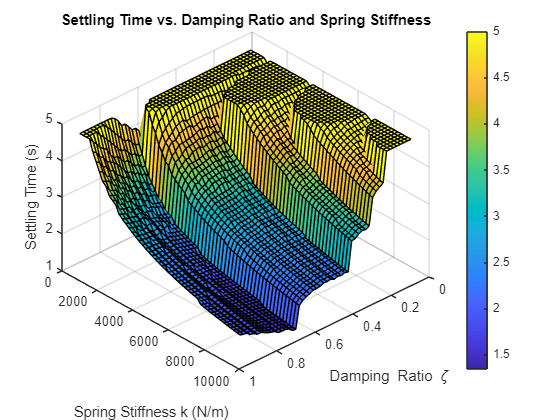


% Plot settling time
figure;
surf(zeta_values, k_values, settling_times);
xlabel('Damping Ratio \zeta');
ylabel('Spring Stiffness k (N/m)');
zlabel('Settling Time (s)');
title('Settling Time vs. Damping Ratio and Spring Stiffness');
colorbar;
grid on;

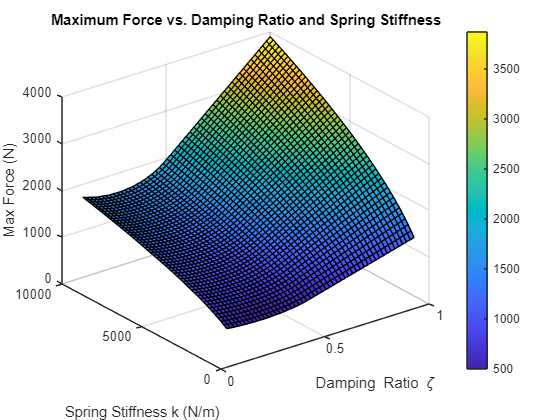


% Plot maximum force
figure;
surf(zeta_values, k_values, max_forces);
xlabel('Damping Ratio \zeta');
ylabel('Spring Stiffness k (N/m)');
zlabel('Max Force (N)');
title('Maximum Force vs. Damping Ratio and Spring Stiffness');
colorbar;
grid on;

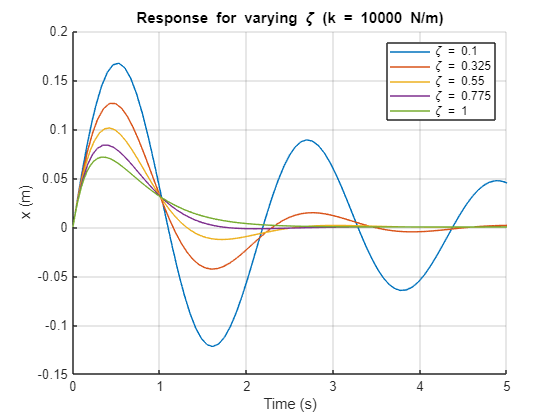


% Response plots for varying zeta at best k
best_k = 10000;
zeta_samples = linspace(min(zeta_values), max(zeta_values), 5);
figure; hold on;
for i = 1:5 % Redo Simulation for Selected Values
    z = zeta_samples(i);
    c = 2*z*sqrt(best_k*m);
    ode = @(t, y)[ y(2); -(c/m)*y(2)-(best_k/m)*y(1) ];
    [t, y] = ode45(ode, tspan, [x0; v0]);
    plot(t, y(:,1), 'DisplayName', ['\zeta = ', num2str(z)]);
end
title(['Response for varying \zeta (k = ', num2str(best_k), ' N/m)']);
xlabel('Time (s)');
ylabel('x (m)');
legend;
grid on;

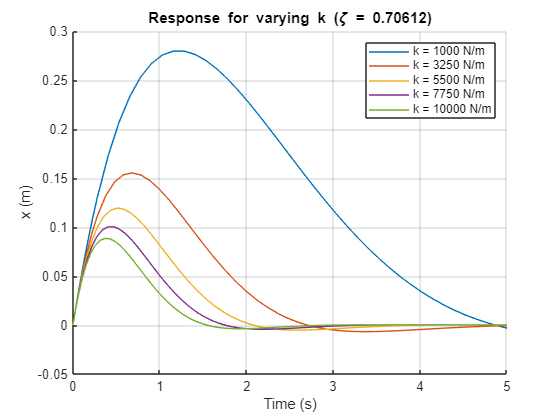


% Response plots for varying k at best zeta
best_zeta = min_zeta;
k_samples = linspace(min(k_values), max(k_values), 5);
figure; hold on;
for i = 1:5 % Redo Simulation for Selected Values
    k = k_samples(i);
    c = 2*best_zeta*sqrt(k*m);
    ode = @(t, y)[ y(2); -(c/m)*y(2)-(k/m)*y(1) ];
    [t, y] = ode45(ode, tspan, [x0; v0]);
    plot(t, y(:,1), 'DisplayName', ['k = ', num2str(round(k)), ' N/m']);
end
title(['Response for varying k (\zeta = ', num2str(best_zeta), ')']);
xlabel('Time (s)');
ylabel('x (m)');
legend;
grid on;

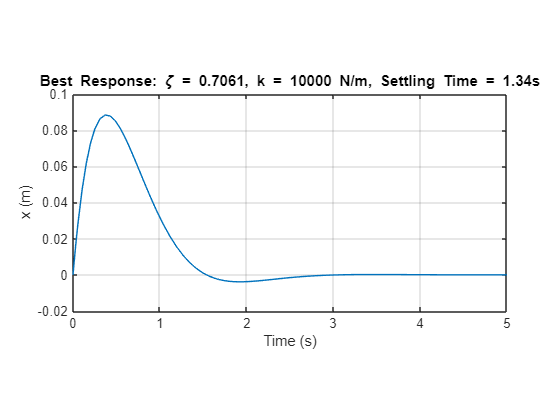


% Response plot for best case
best_c = 2*min_zeta*sqrt(min_k*m);
ode = @(t, y)[ y(2); -(best_c/m)*y(2)-(min_k/m)*y(1) ];
[t, y] = ode45(ode, tspan, [x0; v0]);
figure;
plot(t, y(:,1));
title(['Best Response: \zeta = ', num2str(min_zeta, '%.4f'), ...
       ', k = ', num2str(min_k, '%.0f'), ' N/m, Settling Time = ', ...
       num2str(min_settling_time, '%.2f'), 's']);
xlabel('Time (s)');
ylabel('x (m)');
pbaspect([1, 0.5, 1]);
grid on;